% Read data
clc;clear;

data = readtable('data_part_1.csv', 'ReadVariableNames', true, 'VariableNamingRule','preserve');
data.Properties.VariableNames{1} = 'SampleID';

n_observation = length(data.SampleID);

n_trait = 20;
trait_names = data.Properties.VariableNames(2:21);
n_wave = 1721;
wave_lengths = str2double(data.Properties.VariableNames(22:end));

spectra_data = table2array(data(:,22:end));
trait_data = table2array(data(:,2:21));

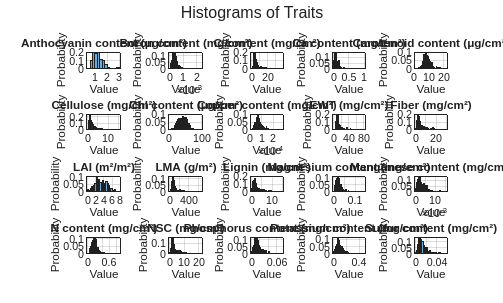

% Distribution of traits
nCols = 5; % Number of columns for subplot grid
nRows = ceil(n_trait / nCols);

figure;
for i = 1:n_trait
    subplot(nRows, nCols, i);
    data_i = trait_data(:, i);
    data_i = data_i(~isnan(data_i));  % remove NaNs
    histogram(data_i, 'Normalization', 'probability');
    title(trait_names{i}, 'Interpreter', 'none');
    xlabel('Value');
    ylabel('Probability');
    grid on;
end
sgtitle('Histograms of Traits');

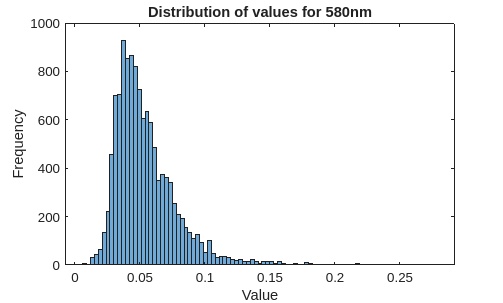

% Distribution of spectra values

figure;
i = 181;
histogram(spectra_data(:,i));
xlabel('Value');
ylabel('Frequency');
title("Distribution of values for "+ wave_lengths(i) + "nm");

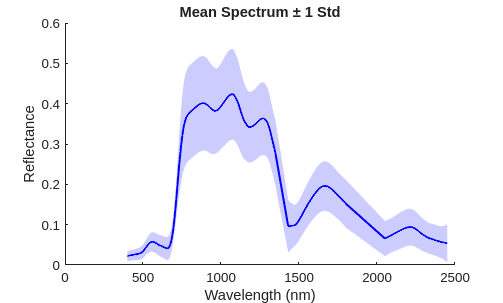


% spectra mean and std plot

mean_spectra = mean(spectra_data, 1, 'omitnan');
std_spectra  = std(spectra_data, 0, 1, 'omitnan');

figure;
clf;
hold on;

plot(wave_lengths, mean_spectra, 'b', 'LineWidth', 1.5);
fill([wave_lengths fliplr(wave_lengths)], ...
     [mean_spectra-std_spectra fliplr(mean_spectra+std_spectra)], ...
     'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
xlabel('Wavelength (nm)');
ylabel('Reflectance');
title('Mean Spectrum ± 1 Std');

% Compute PCA
spectra_data_normalized = (spectra_data - mean_spectra)./std_spectra;
[coeff, score, latent, tsquared, explained] = pca(spectra_data_normalized, 'Algorithm','svd');

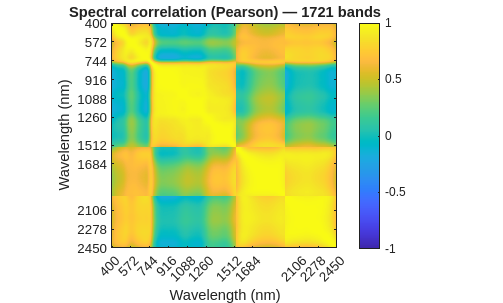

% Correlation visualization

% sample if want to show less
selected_bands_numbers = n_wave;                             
idx = 1:n_wave;
spectra_data_normalized_s  = spectra_data_normalized(:, idx);
wave_lengths_s = wave_lengths(idx);

% correlation
corrType = 'Pearson';
R = corr(spectra_data_normalized_s, 'Type', corrType, 'Rows', 'pairwise');

% heatmap
figure; 
clf;
imagesc(wave_lengths_s, wave_lengths_s, R, [-1 1]); axis image; colormap(parula); colorbar;
xlabel('Wavelength (nm)'); ylabel('Wavelength (nm)');
title(sprintf('Spectral correlation (%s) — %d bands', corrType, numel(idx)));
set(gca,'XTick',wave_lengths_s(1:round(numel(wave_lengths_s)/10):end), ...
        'YTick',wave_lengths_s(1:round(numel(wave_lengths_s)/10):end));

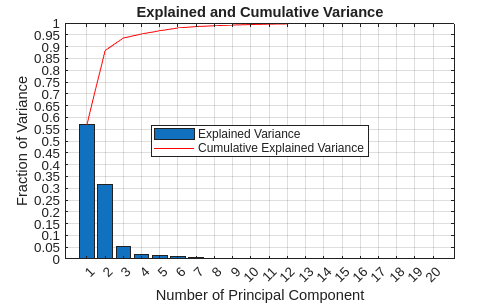

% Plot Explained Variance

figure;
n_plot = 20;
explained_norm = explained / 100;
cumulativeExplained = cumsum(explained_norm);

bar(explained_norm(1:n_plot, 1));
hold on;
plot(cumulativeExplained(1:n_plot, 1),'r');
hold off;

xlabel('Number of Principal Component');
ylabel('Fraction of Variance');
ylim([0 1]);
legend('Explained Variance','Cumulative Explained Variance','Location','best');
title('Explained and Cumulative Variance');
xticks(1:n_plot);
yticks(0:0.05:1);
grid on;

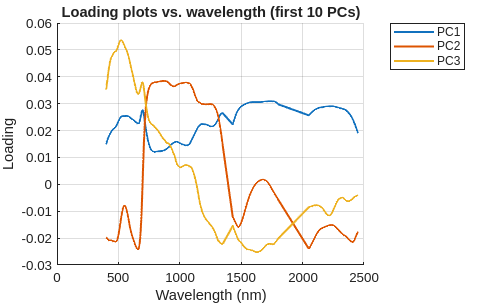

% Loading plots
figure();
clf; 
hold on;

numPC = 3;
colors = lines(numPC);

for k = 1:numPC
    plot(wave_lengths, coeff(:,k), 'LineWidth', 1.5, 'Color', colors(k,:));
end

xlabel('Wavelength (nm)'); 
ylabel('Loading');
legend("PC"+string(1:numPC), 'Location','bestoutside');
title('Loading plots vs. wavelength (first 10 PCs)');
grid on;

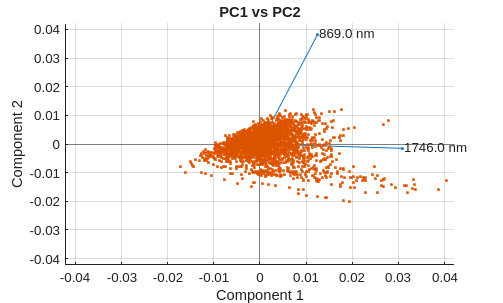

% Biplot

numPCs = 10;

% Find the top variable for each PC
topVarIdx = zeros(1, 2);
[~, topVarIdx(1)] = max(abs(coeff(:,1)));
[~, topVarIdx(2)] = max(abs(coeff(:,2)));

% Plot pairs of PCs with their top variable
figure;
theseVars = [topVarIdx(1), topVarIdx(2)];  % top variable from each PC

% Make wavelength labels
varLabels = arrayfun(@(x) sprintf('%.1f nm', wave_lengths(x)), ...
                     theseVars, 'UniformOutput', false);

biplot(coeff(theseVars,1:2), ...
       'Scores', score(:,1:2), ...
       'VarLabels', varLabels);
title(['PC1 vs PC2']);